Contagious Diseases Group Assignment 2 Ebola Outbreak

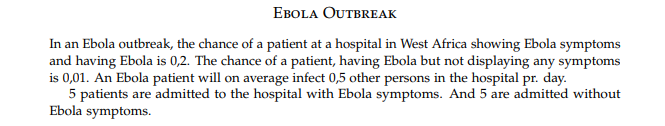

E_Having_With_Symptoms=0.2

E_Having_With_Symptoms = 0.2000

E_having_No_symtoms=0.01

E_having_No_symtoms = 0.0100


E_having_infect=0.5 %persons in hospital pr day

E_having_infect = 0.5000


Patient_admitted_With_symtoms=5

Patient_admitted_With_symtoms = 5

Patients_admitted_without_symptoms=5

Patients_admitted_without_symptoms = 5

Event a har ebola  

Event b har ebola uden symptomer

Total_probabiltiy= E_Having_With_Symptoms+E_having_No_symtoms

Total_probabiltiy = 0.2100


$$\mathrm{Pr}\left(\overset{-}{B} |A\right)$$
 

Having_No_Symptoms_prop = E_having_No_symtoms/Total_probabiltiy

Having_No_Symptoms_prop = 0.0476

Vi deler grupperne op. 

Event A = Har symptomer og ebola

Event B = Har ikke symptomer men ebola

Vi antager uafhængighed mellem A og B. 

% P_A = 1 - P_NA
% P_B = 1 - P_NB

% P_NA = Sandsynlighed for at 0 patienter har ebola, men viser 
% symptomer
k = 0;
n = Patient_admitted_With_symtoms;
nk_A = factorial(n)/(factorial(k)*factorial(n-k));
P_NA = nk_A *E_Having_With_Symptoms^k*(1-E_Having_With_Symptoms)^(n-k)

P_NA = 0.3277


% P_NB = Sandsynlighed for at 0 patienter har ebola, men viser
% ikke symptomer
n = Patients_admitted_without_symptoms;
nk_B = factorial(n)/(factorial(k)*factorial(n-k));
P_NB = nk_B * E_having_No_symtoms^k*(1-E_having_No_symtoms)^(n-k)

P_NB = 0.9510


P_A = 1 - P_NA;
P_B = 1 - P_NB;

% Side 18 formelsamling - Inklusion/Eksklusion
Facit = P_A + P_B - (P_A*P_B)

Facit = 0.6884

. You know that only one of the patients have Ebola, but not which one. How many of the patients do you need to test on average to find the infected patient? 

% N = lige
n = 10;
res = 0.5*((n/2) + (n+2)/2)

res = 5.5000

k=2

k = 2

%   Number of outcomes where all three take places
out = factorial(n) / (factorial(k)*factorial(n-k))

out = 45

45 kombinationer. En rækker følge er korrekt

1/45